% Read in file, define inital parameters and variables
clear all;
fig=gcf;
fig.Position(4)=210;

a = load("22steps.mat").Acceleration;
calibration_time = 3;
f=10;

% Is the phone position stationary?
stationary = true;

% In case phone position is stationary, set up the gravity
gravity_x = 0;
gravity_y = 0;
gravity_z = 9.8;
gravity = sqrt(gravity_x^2 + gravity_y^2 + gravity_z^2);

t = a.Timestamp.Second - a.Timestamp.Second(1);
t(t<0) = t(t<0) + 60;

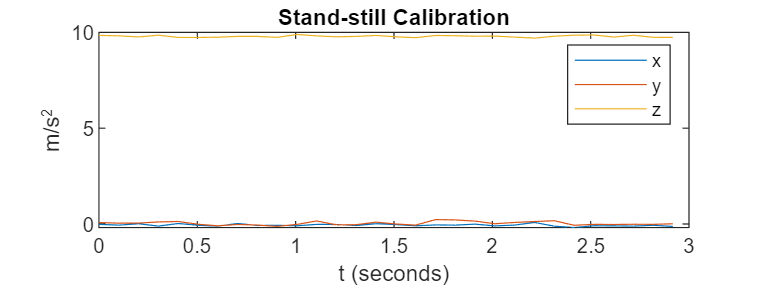

% Calibration
calib_idx = calibration_time * f;
tc = t(1:calib_idx);
xc = a.X(1:calib_idx);
yc = a.Y(1:calib_idx);
zc = a.Z(1:calib_idx);

plot(tc,[xc yc zc]);
legend('x','y','z');
title('Stand-still Calibration');
xlabel('t (seconds)');
ylabel('m/s^2');


if stationary
    % Use linear regression to get the bias values
    T = [ones(length(tc),1) tc];
    line_x = T\xc;
    X0 = line_x(1) - gravity_x
    line_y = T\yc;
    Y0 = line_y(1) - gravity_y
    line_z = T\zc;
    Z0 = line_z(1) - gravity_z
else
    [X0, Y0, Z0] = deal(0,0,0)
end

X0 = -0.0283

Y0 = 0.0299

Z0 = -0.0049

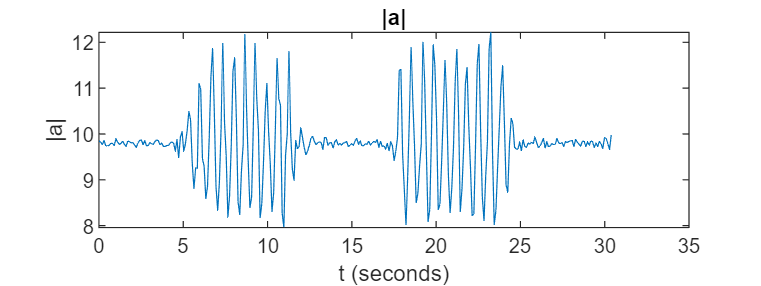

% Plot the norm by time
a_norm = ((a.X-X0).^2 + (a.Y-Y0).^2 + (a.Z-Z0).^2).^0.5;
plot(t, a_norm);
title('|a|');
xlabel('t (seconds)')
ylabel('|a|')

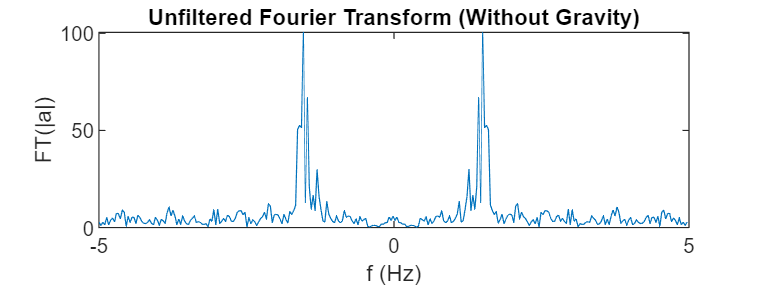

% Plot the Fourier transform of the norm
a_tf = fft(a_norm - gravity);
a_tf = fftshift(a_tf);
L = length(a_norm);
freqs = f/L * linspace(0,L-1,L) - f/2;
plot(freqs,abs(a_tf));
title('Unfiltered Fourier Transform (Without Gravity)')
xlabel('f (Hz)')
ylabel('FT(|a|)')

% Check if frequency varies for the sample
[pks,loc] = findpeaks(abs(a_tf), freqs);
l = ceil(length(loc)/2);
[mu,sig] = normal_dist(loc(l:end),pks(l:end));
fprintf('Distribution: N(mu = %2.4f, sigma = %2.4f)',mu,sig)

Distribution: N(mu = 2.0494, sigma = 0.4612)

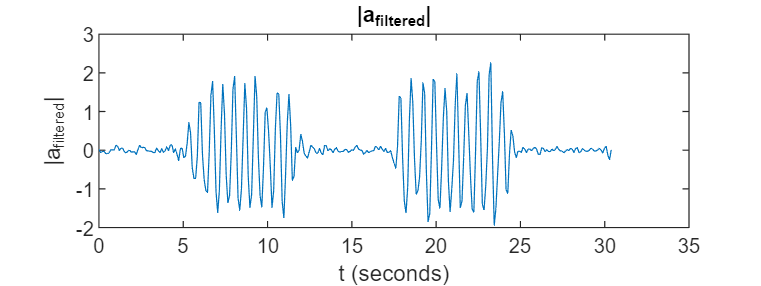

% Set up filter
fmin = mu - 3*sig;
fmax = mu + 3.5*sig;
% Filter
a_filtered = bandpass(a_norm,[fmin,fmax],f);
plot(t, a_filtered);
title('|a_{filtered}|');
xlabel('t (seconds)')
ylabel('|a_{filtered}|')

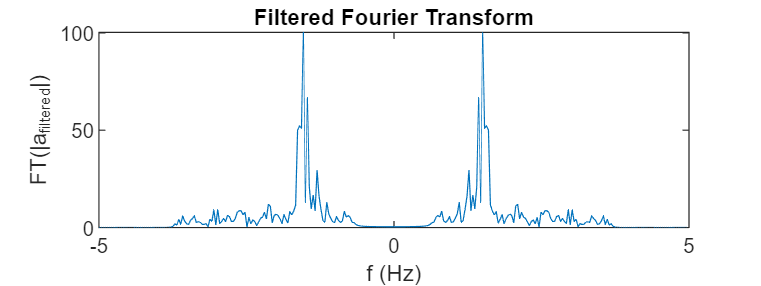

% Plot Fourier Transform of the filtered signal 
af_tf = fft(a_filtered);
af_tf = fftshift(af_tf);
plot(freqs,abs(af_tf));
title('Filtered Fourier Transform')
xlabel('f (Hz)')
ylabel('FT(|a_{filtered}|)')

% Use calibration segment to identify max prominence noise
[~,~,~,pc] = findpeaks(a_filtered(1:calib_idx), freqs(1:calib_idx), 'SortStr','descend');

% Ensure margin is large enough to prevent noise peaks
b_norm = (X0^2+Y0^2+Z0^2)^0.5;
if b_norm > 0.2 margin=b_norm; else margin=0.2; end 

minP = pc(1) + margin; % Add bias norm as safe margin

% Get the highest likely step frequency in the data
maxStepFreq = mu + 4*sig;

% Set up peak-finding parameters
settings = struct('MinPeakDistance', 1/maxStepFreq, ...
                  'MinPeakProminence', minP);

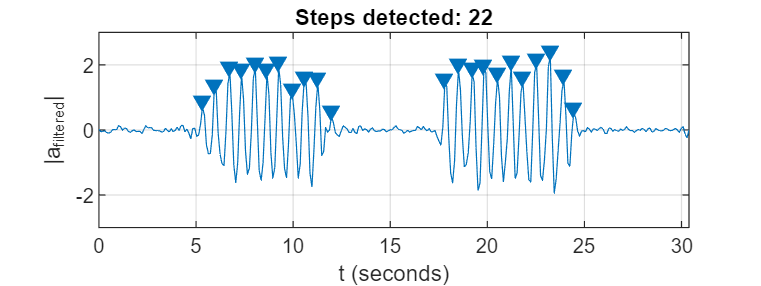

% Find peaks that correspond to steps
findpeaks(a_filtered,t,settings);
ps = findpeaks(a_filtered,t,settings);
title(sprintf('Steps detected: %d',length(ps)));
xlabel('t (seconds)')
ylabel('|a_{filtered}|')

function [mu,sig] = normal_dist(x,p)
    sum_x = 0;
    sum_var = 0;

    sum_p = sum(p);
    for i=1:length(x)
        sum_x = sum_x + x(i)*p(i)/sum_p;
    end
    mu = sum_x;
    for i=1:length(x)
        sum_var = sum_var + (x(i)-mu)^2;
    end
    sig = sqrt(sum_var/sum_p);
end